# 模拟退火

已知全国34个省会城市（包括直辖市、自治区首府和港澳台）的经纬度坐标（第一个为北京）；现在需要从北京出发，到所有城市视察，要求每个城市**只能到达一次**，并最终回到北京。求视察路线方案，使得总路径最短。

### 1、导入数据

因为题目提供的数据是经纬度，注意第一列是经度、第二列是纬度，写函数时不要写错了

求两个城市间距离，是求在地球上的弧线长度，也就是求一个**扇形的弧长**。

**可使用distance函数求球体上两点间距离**

d(i,j) = distance(lat1,lon1,lat2,lon2,radius);其中lat1、lon1是第一个点的**纬度和经度**，lat2,lon2是第二个点的纬度和经度，radius是球体的半径

clc, clear, close all

%数据在文件cities.xlsx中，注意要放在与本文件同一文件夹下
city = table2array(readtable('citys.xlsx','Range','B2:C35'));
n = size(city,1);      %城市距离初始化                                                                    
d = zeros(n,n+1);      %35号只会作为终点          
for i = 1:n
    for j = 1:n
            d(i,j)= distance(city(i,2),city(i,1),city(j,2),city(j,1),6371); % distance求圆心角的角度.第一个点的纬度、第一个点的经度
    end    
end
%各城市到35号即北京的距离作为第35列
for i=1:n
    d(i,35)= distance(city(i,2),city(i,1),city(1,2),city(1,1),6371);
end

### **2、蒙特卡罗法求初始解**

之前讲过蒙特卡罗法。本题总共34个城市，从1号城市北京出发，遍历完所有34个城市后，返回北京，设返回的北京为第35号。

每次随机选一种路径方案，出北京外的其他33个城市，利用randperm(33)为33个从1到33的整数随机排列；那么1+randperm(33)就是2到34的整数随机排列。

path=[];
lenth=inf; %总路径及长度初始化
for j=1:1000  %求较好的初始解，随机求1000种方案，挑出最好的作为初始方案
    temp_path=[1 1+randperm(33) 35];    % 当前解（方案）
    temp_lenth=0;   % 当前方案的总路径
    % 求该方案下总路径长度temp_lenth
    for i=1:34
        temp_lenth=temp_lenth+d(temp_path(i),temp_path(i+1));
    end
    % 如果该方案下总路径长度temp小于所记录的当前最短总路径长度long（初始为正无穷）
    if temp_lenth<lenth
        path=temp_path; lenth=temp_lenth;      % 将该路径方案temp_path记为最短路径方案path，将该方案的长度temp_lenth记为最短路径长度lenth
    end
    % 如此循环1000次，就从1000个随机方案里挑选出最优的方案作为初始方案，用于后面的模拟退火
end


3、模拟退火

- while循环实现温度不断降低，温度初试为1，每次新的温度是之前的0.999倍；当温度低于10^(-30)时终止循环。

- while循环内嵌套for循环，实现固定温度下的马尔科夫过程，即不断求新解、并判断是否接受。

- 判断是否接受新解，就是代码中的if和elseif两种情况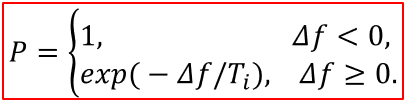

e=0.1^30;alpha=0.999;T=1;markov=1;   %这些参数都是可以改的

% for k=1:L  %退火过程
accept=0;rand_accept=0;refuse=0;
while T>e
    for t=1:markov
        %新解随机选序号𝑢, 𝑣，将𝑢到𝑣的这部分转为逆序作为新解
        c=2+floor(33*rand(1,2));  %产生新解；floor向下取整，得到两个2到34的随机整数
        c=sort(c);  %随机选的两个点升序排序，用于接下来计算
        u=c(1);v=c(2);  %模型中的随机选的两个点u和v，u是序号小的那一个
        %计算目标函数值的增量
        df=d(path(u-1),path(v))+d(path(u),path(v+1))-...
            d(path(u-1),path(u))-d(path(v),path(v+1));
        if df<0 %接受准则
            path=[path(1:u-1),path(v:-1:u),path(v+1:35)]; %新路径u到v逆序
            lenth=lenth+df; 
            accept=accept+1;
        elseif exp(-df/T)>=rand   %rand产生0到1的随机数；不等号左边与温度T有关
            path=[path(1:u-1),path(v:-1:u),path(v+1:35)]; 
            lenth=lenth+df;
            rand_accept=rand_accept+1;
        else
            refuse=refuse+1;
        end
    end
    T=T*alpha;
end

path(35)=1;     % 1号和35号都是北京，把35改成1，方便画图
plot(city(path ,1), city(path ,2),'o-');
    disp('最短路程：')

最短路程：


    disp(lenth)

   1.4029e+04



    disp('直接接受新解次数：')

直接接受新解次数：


    disp(accept)

   741



    disp('接受更差的随机解次数：')

接受更差的随机解次数：


    disp(rand_accept)

        1282



    disp('不接受随机解次数：')

不接受随机解次数：


    disp(refuse)    

       67021



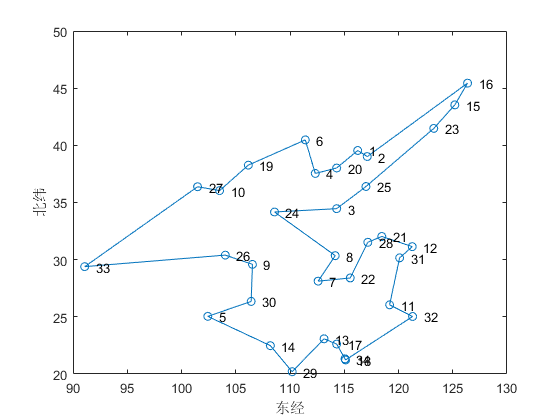

for i = 1:n
    %对每个城市进行标号
    text(city(i,1),city(i,2),['   ' num2str(i)]); %number to string
end
xlabel('东经')
ylabel('北纬')


% 本文件出自b站/公众号：数学建模BOOM
% 关注微信公众号：数学建模BOOM，回复"课程"
% 查看全套视频课程+配套PPT课件+代码文件